% Quaternion from RViz (x, y, z, w)
q_rviz = [-0.202834, 0.433631, 0.795263, -0.371993];  % Replace with actual values
% Position from RViz (x,y,z)
o_rviz = [-0.0979979; 0.093209; 0.316132];
theta_rviz = [0.875,-0.203,0.577,0.517,0];

q_matlab = [q_rviz(4), q_rviz(1), q_rviz(2), q_rviz(3)];
% quat = quaternion(q_matlab);  % Requires Aerospace Toolbox
R = eul2rotm(quat2eul(q_matlab,"ZYX"),"ZYX");    % 'frame' for active rotation (DH style)
H = [R,o_rviz;0,0,0,1];

d =         [0.0563, 0, 0, 0, 0, 0.114];
a =         [0, 0.1093, 0.100512, 0, 0, -0.007];
theta0 =    [pi/2, -1.4350, -0.028647, pi/2, 0];

theta_set = theta_rviz + theta0

theta_set =     2.4458   -1.6380    0.5484    2.0878         0


theta = ik_geometric(H,d,a)

W = 0.8521

theta =     2.4016   -1.6391    0.5508    2.0863


mean_abs_error = mean(abs(abs(theta_set(1:numel(theta)))-abs(theta)));
disp("Mean abs. error in deg:")

Mean abs. error in deg:


disp(rad2deg(mean_abs_error))

    0.7046



% H = generate_desired_pose(-0.0979979,0.093209,0.216132,0,0)
H = generate_desired_pose(0.01,0.01,0.1,0,0)

H =    -0.7071   -0.0000    0.7071    0.0100
    0.7071    0.0000    0.7071    0.0100
   -0.0000    1.0000    0.0000    0.1000
         0         0         0    1.0000


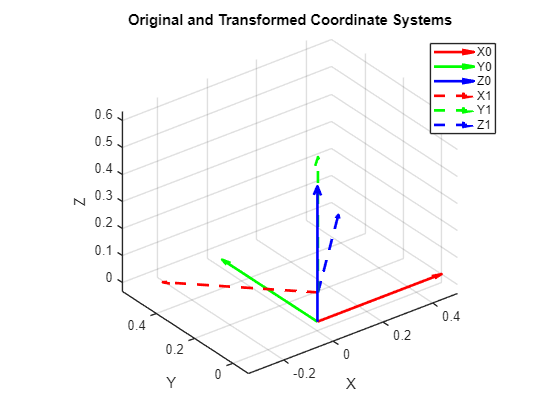

plotCoordinateSystems(H)

theta = ik_geometric(H,d,a)

theta =    -2.4262   -1.3675    2.0494   -2.2527


T = eye(4,4);
for i=1:numel(theta)
    T = T * getDHmatrix(theta(i),d(i),a(i),alpha(i))
end

Error using alpha
Too many output arguments.

function H = generate_desired_pose(x,y,z,psi,phi)
    d = [x,y,z]';
    theta1 = atan2(y,x);
    R_z_theta = [cos(theta1), -sin(theta1)  , 0;...
                 sin(theta1), cos(theta1)   ,  0;...
                 0          , 0             ,  1];
    R_z_90 =  [cos(pi/2)    , -sin(pi/2)   , 0;...
               sin(pi/2)    , cos(pi/2)    , 0;...
               0            , 0             , 1];
    R_y_90  = [cos(pi/2)    , 0             , sin(pi/2);...
               0            , 1             , 0;...
               -sin(pi/2)   , 0             ,  cos(pi/2)];
    R_x_psi = [1            , 0             , 0;...
               0            , cos(psi), -sin(psi);...
               0            , sin(psi),  cos(psi)];
    R_z_phi = [cos(phi)     , -sin(phi)     , 0;...
                 sin(phi)   , cos(phi)      ,  0;...
                 0          , 0             ,  1];

    R = R_z_theta*R_y_90*R_z_90*R_x_psi*R_z_phi;

    H = [R,d;0,0,0,1];

end

function theta = ik_geometric(H,d,a)
R_tcp = H(1:3,1:3);
o_tcp = H(1:3,4);

o_3 = o_tcp - d(6)*R_tcp*[0;0;1] - a(6)*R_tcp*[1;0;0];
x_o3 = o_3(1);
y_o3 = o_3(2);
z_o3 = o_3(3);

r = sqrt(x_o3^2 + y_o3^2);
s = z_o3 - d(1);
W = (r^2 + s^2 - a(2)^2 - a(3)^2)/(2*a(2)*a(3));

theta(1) = atan2(y_o3,x_o3);
theta(3) = atan2(sqrt(1-W^2),W);
theta(2) = -(atan2(s,r) - atan2(a(3)*sin(-theta(3)),a(2) + a(3)*cos(-theta(3))) );

Y = cos(theta(1))*cos(theta(2)+theta(3))*R_tcp(1,3) + ...
    sin(theta(1))*cos(theta(2)+theta(3))*R_tcp(2,3) - ...
    sin(theta(2)+theta(3))*R_tcp(3,3);
X = cos(theta(1))*sin(theta(2)+theta(3))*R_tcp(1,3) + ...
    sin(theta(1))*sin(theta(2)+theta(3))*R_tcp(2,3) + ...
    cos(theta(2)+theta(3)) * R_tcp(3,3);

theta(4) = atan2(Y,X);
% theta(5) = 

end

function plotCoordinateSystems(H)
    % Input:
    % H - 4x4 homogeneous transformation matrix
    
    % Original coordinate system at origin
    origin = [0; 0; 0];
    X0 = [1; 0; 0];
    Y0 = [0; 1; 0];
    Z0 = [0; 0; 1];

    % Transformed coordinate system
    R = H(1:3,1:3);
    t = H(1:3,4);

    X1 = R(:,1);
    Y1 = R(:,2);
    Z1 = R(:,3);
    
    % Plot original frame
    figure; hold on; grid on; axis equal;
    quiver3(origin(1), origin(2), origin(3), X0(1), X0(2), X0(3), 0.5, 'r', 'LineWidth', 2);
    quiver3(origin(1), origin(2), origin(3), Y0(1), Y0(2), Y0(3), 0.5, 'g', 'LineWidth', 2);
    quiver3(origin(1), origin(2), origin(3), Z0(1), Z0(2), Z0(3), 0.5, 'b', 'LineWidth', 2);

    % Plot transformed frame
    quiver3(t(1), t(2), t(3), X1(1), X1(2), X1(3), 0.5, 'r--', 'LineWidth', 2);
    quiver3(t(1), t(2), t(3), Y1(1), Y1(2), Y1(3), 0.5, 'g--', 'LineWidth', 2);
    quiver3(t(1), t(2), t(3), Z1(1), Z1(2), Z1(3), 0.5, 'b--', 'LineWidth', 2);

    % Labels
    legend({'X0','Y0','Z0','X1','Y1','Z1'}, 'Location','best');
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    title('Original and Transformed Coordinate Systems');
    view(3);
end

function T = getDHmatrix(theta,d,a,alpha)
    T = zeros(4,4);
    
    T(1,1) = cos(theta);
    T(1,2) = -sin(theta)*cos(alpha);
    T(1,3) = sin(theta)*sin(alpha);
    T(1,4) = a*cos(theta);

    T(2,1) = sin(theta);
    T(2,2) = cos(theta)*cos(alpha);
    T(2,3) = -cos(theta)*sin(alpha);
    T(2,4) = a*sin(theta);

    T(3,2) = sin(alpha);
    T(3,3) = cos(alpha);
    T(3,4) = d;

    T(4,4) = 1;
end
